clc,clear,close all
x = [1,2,3,4,5];
y = [4,4.5,6,8,8.5];
omega = [2 1 3 1 1];
syms t
varphi = [1,t,t^2];
n = length(varphi);
G = zeros(n);
d = zeros(n,1);
for i = 1:n
    for j = 1:n
        G(i,j) = sum(subs(varphi(i),t,x).*subs(varphi(j),t,x).*omega);
    end
end
for i = 1:n
    d(i) = sum(subs(varphi(i),t,x).*y.*omega);
end
a = G\d;


plot(x,y,'*');
xx = linspace(x(1),x(end),100);
syms x
S = vpa(subs(sum(varphi.*a'),t,x),4);
disp('拟合函数为')

拟合函数为


disp(S)

$$0.06944\,x^{2}+0.8102\,x+3.005$$

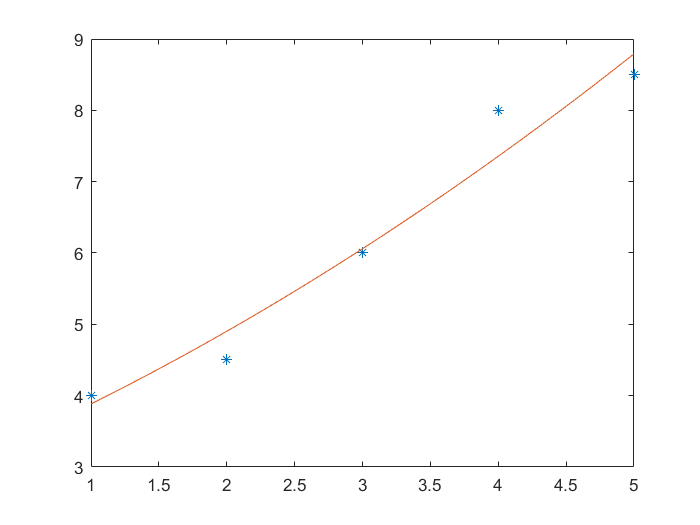


yy = vpa(subs(S,x,xx));
hold on
plot(xx,yy)